figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
subplotsize=[8 4];
disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')

This is the distribution of the indiviudal T value(across columns) for the three contrast


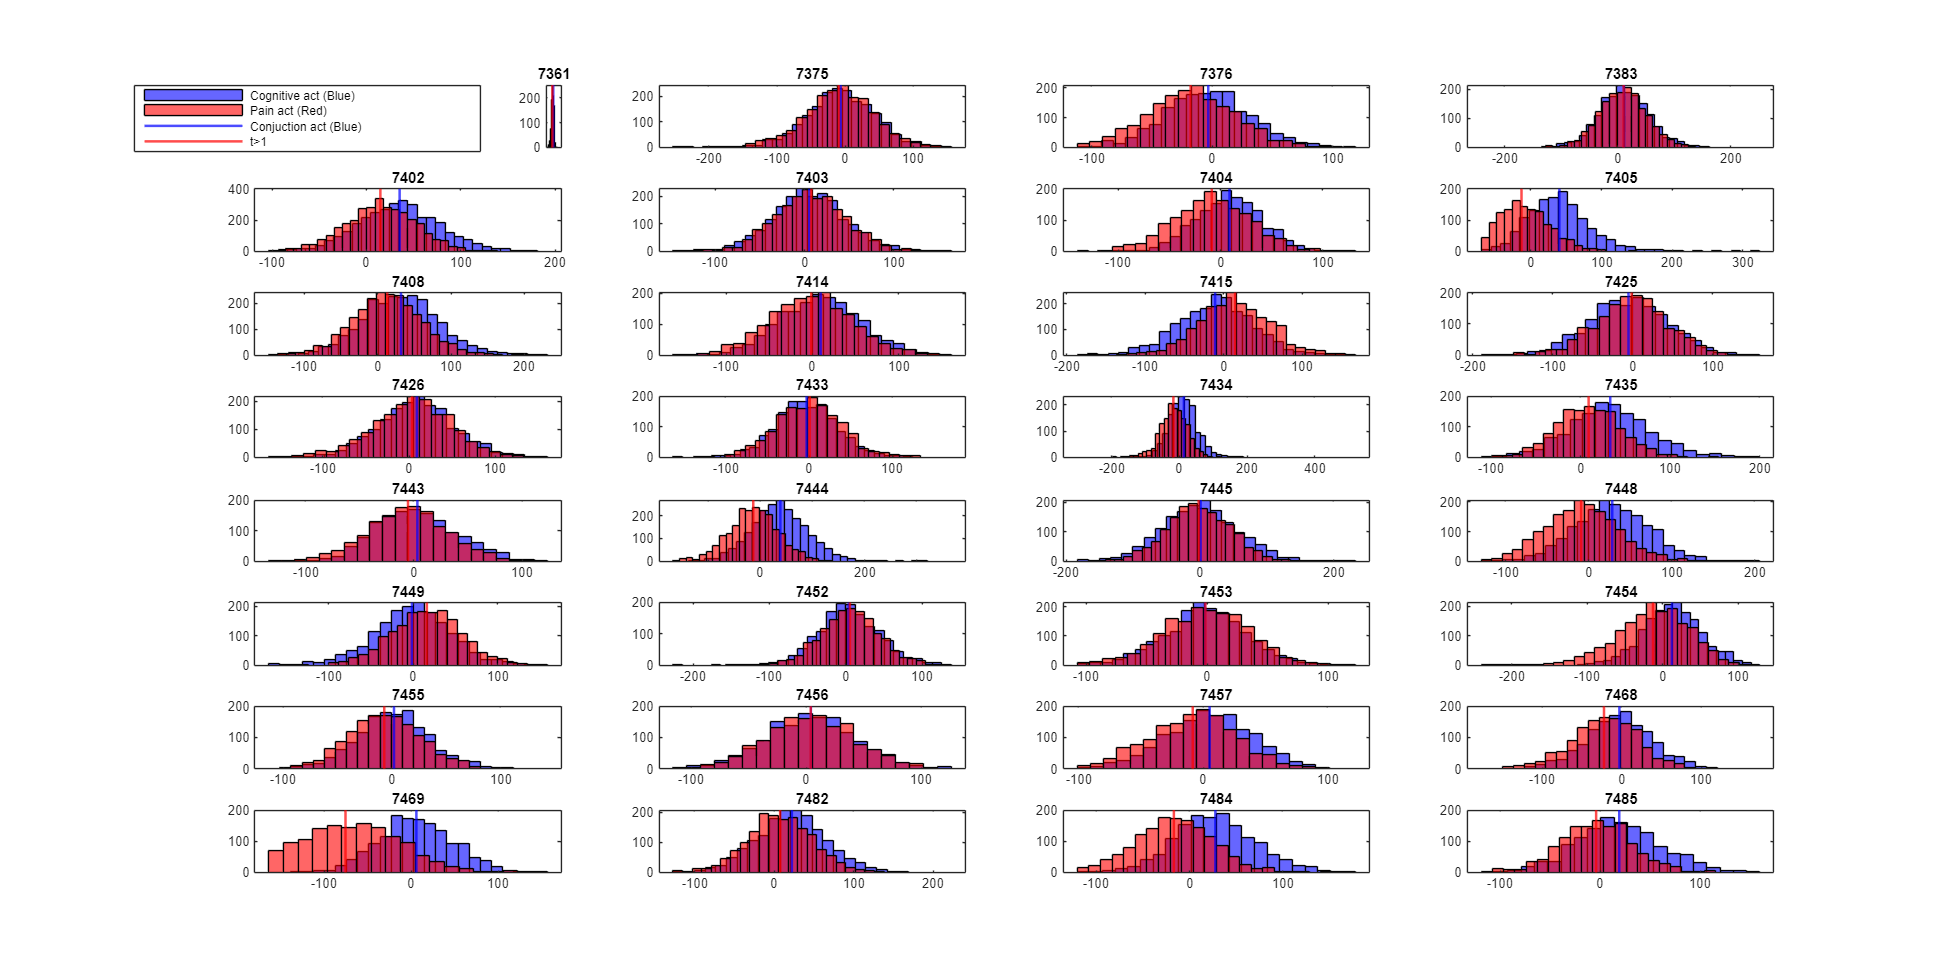

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Time for one subject to process:Elapsed time is 2.411570 seconds.


7375 subject columnar info r


Time for one subject to process:Elapsed time is 2.570089 seconds.


7376 subject columnar info r


Time for one subject to process:Elapsed time is 2.202509 seconds.


7383 subject columnar info r


Time for one subject to process:Elapsed time is 2.171898 seconds.


7402 subject columnar info r


Time for one subject to process:Elapsed time is 4.180941 seconds.


7403 subject columnar info r


Time for one subject to process:Elapsed time is 2.599235 seconds.


7404 subject columnar info r


Time for one subject to process:Elapsed time is 1.986860 seconds.


7405 subject columnar info r


Time for one subject to process:Elapsed time is 1.826545 seconds.


7408 subject columnar info r


Time for one subject to process:Elapsed time is 3.105336 seconds.


7414 subject columnar info r


Time for one subject to process:Elapsed time is 2.301492 seconds.


7415 subject columnar info r


Time for one subject to process:Elapsed time is 2.815686 seconds.


7425 subject columnar info r


Time for one subject to process:Elapsed time is 2.267953 seconds.


7426 subject columnar info r


Time for one subject to process:Elapsed time is 2.425314 seconds.


7433 subject columnar info r


Time for one subject to process:Elapsed time is 2.143340 seconds.


7434 subject columnar info r


Time for one subject to process:Elapsed time is 2.424477 seconds.


7435 subject columnar info r


Time for one subject to process:Elapsed time is 1.997506 seconds.


7443 subject columnar info r


Time for one subject to process:Elapsed time is 2.127638 seconds.


7444 subject columnar info r


Time for one subject to process:Elapsed time is 3.049884 seconds.


7445 subject columnar info r


Time for one subject to process:Elapsed time is 2.345491 seconds.


7448 subject columnar info r


Time for one subject to process:Elapsed time is 2.149974 seconds.


7449 subject columnar info r


Time for one subject to process:Elapsed time is 2.333879 seconds.


7452 subject columnar info r


Time for one subject to process:Elapsed time is 2.149197 seconds.


7453 subject columnar info r


Time for one subject to process:Elapsed time is 2.430115 seconds.


7454 subject columnar info r


Time for one subject to process:Elapsed time is 2.387877 seconds.


7455 subject columnar info r


Time for one subject to process:Elapsed time is 2.029490 seconds.


7456 subject columnar info r


Time for one subject to process:Elapsed time is 2.076623 seconds.


7457 subject columnar info r


Time for one subject to process:Elapsed time is 2.121867 seconds.


7468 subject columnar info r


Time for one subject to process:Elapsed time is 1.838904 seconds.


7469 subject columnar info r


Time for one subject to process:Elapsed time is 2.145513 seconds.


7482 subject columnar info r


Time for one subject to process:Elapsed time is 2.300034 seconds.


7484 subject columnar info r


Time for one subject to process:Elapsed time is 2.442391 seconds.


7485 subject columnar info r


Time for one subject to process:Elapsed time is 2.212949 seconds.


for subj=allsubj%{7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls.mat'];
    if exist(columnartsfile,"file")
%         disp(subj)
        disp([num2str(subj{:}) ' subject columnar info r'])
        plotidx=plotidx+1;
        [stat,columndistribution,~]=BK_layer_sampling_pain_study_pipeline(subj);
        allsubjcoldistr{plotidx}=columndistribution;
        allsubjstat{plotidx}=stat;
        subplot(subplotsize(1), subplotsize(2), plotidx);
        hcogn=histogram(stat.beta(:,:,1),'BinLimits',[min(stat.beta(:,:,1)),max(stat.beta(:,:,1))],'FaceColor', 'blue');
        hold on
        hpain=histogram(stat.beta(:,:,2),'BinLimits',[min(stat.beta(:,:,1)),max(stat.beta(:,:,1))],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
        xline(mean(stat.beta(:,:,1)),'-','LineWidth', 1.5,'Color', 'blue');
        xline(mean(stat.beta(:,:,2)),'-','LineWidth', 1.5,'Color', 'red');
        title(num2str(subj{:}))
        if plotidx==1
            legend('Cognitive act (Blue)', 'Pain act (Red)','Conjuction act (Blue)','t>1', 'Location', 'northwestoutside');
        end
        
        hold off
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

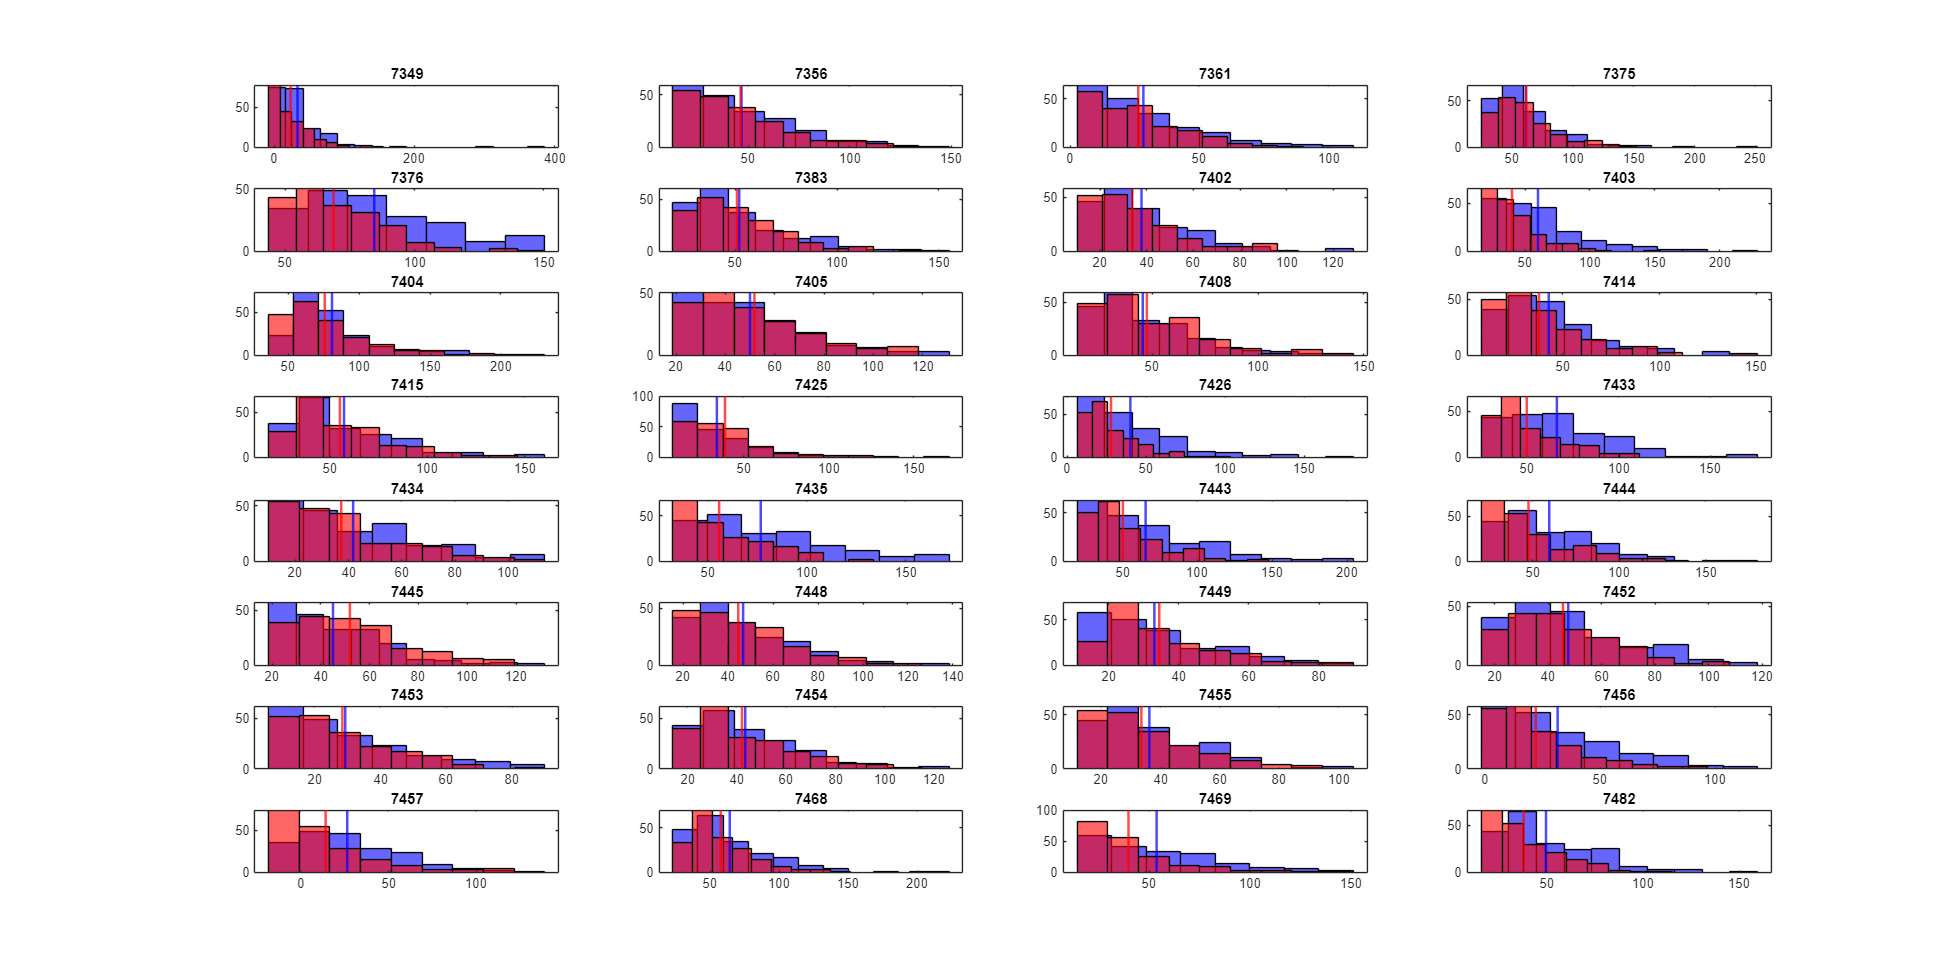

figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
for subj=1:length(allsubjstat)%{7484,7485}
        plotidx=plotidx+1;
        stat=allsubjstat{subj};
        [top200Values, top200Indices] = maxk(stat.T(:,1,3),200);
        subplot(subplotsize(1), subplotsize(2), plotidx);
        hcogn=histogram(stat.beta(top200Indices,:,1),'BinLimits',[min(stat.beta(top200Indices,:,1)),max(stat.beta(top200Indices,:,1))],'FaceColor', 'blue');
        hold on
        hpain=histogram(stat.beta(top200Indices,:,2),'BinLimits',[min(stat.beta(top200Indices,:,1)),max(stat.beta(top200Indices,:,1))],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
        xline(mean(stat.beta(top200Indices,:,1)),'-','LineWidth', 1.5,'Color', 'blue'); %cognition
        xline(mean(stat.beta(top200Indices,:,2)),'-','LineWidth', 1.5,'Color', 'red'); %pain
        title(num2str(allsubj{subj}))
        
        hold off
    

end


%check the column size

figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
subplotsize=[8 4];
disp('This is the cortical thickness of the ROI derived from MATLAB')

This is the cortical thickness of the ROI derived from MATLAB



for subid=allsubj%
    if ~ischar(subid)
        subid = char(string(subid));
    end
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    inputpath=[roipath subid '\functionalmasks\'];
    myfile=[inputpath 'interimdata_rwls.mat'];
    if exist(myfile,"file")
        load(myfile,'interimdata_columns')
        plotidx=plotidx+1;
        subplot(subplotsize(1), subplotsize(2), plotidx);
        histogram(interimdata_columns.allroicolumnsize)
        mytitle=[subid 'subject: ' num2str(mean(interimdata_columns.allroicolumnsize)) 'mm'];
        title(mytitle)
    end
end


% histogram(allsubjcoldistr{:}.numberofcolumnsinmask)

%load the data
for subj=1:length(allsubjcoldistr)
    wholmask(subj)=allsubjcoldistr{subj}.numberofcolumnsinmask;
    conjuction_posvoxelnumdistr(subj)=allsubjcoldistr{subj}.numberofactcolumnsbasedonconj(1);
    cogn_posvoxelnumdistr(subj)=allsubjcoldistr{subj}.numberofcognactivcolumn(1);
    pain_posvoxelnumdistr(subj)=allsubjcoldistr{subj}.numberofpainactivecolumns(1);
    
end

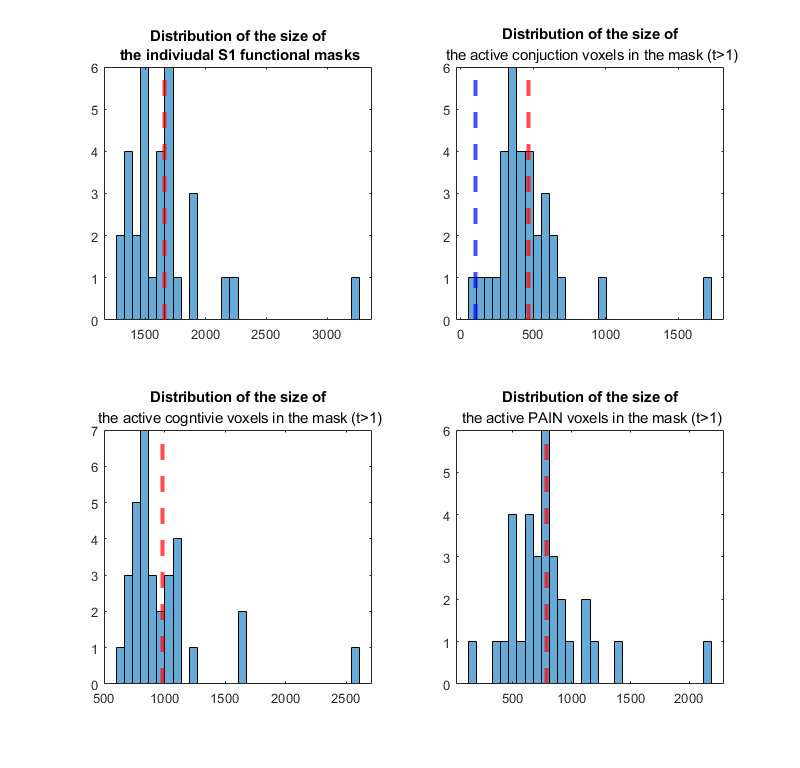

figure('Position', [100, 100, 2400, 1200]);
subplot(2,2,1)
histogram(wholmask,30)
hold on
xline(mean(wholmask),'--','LineWidth', 3,'Color', 'red');
title({'Distribution of the size of',...
    ' the indiviudal S1 functional masks'})
hold off
subplot(2,2,2)
histogram(conjuction_posvoxelnumdistr,30)
hold on
xline(mean(conjuction_posvoxelnumdistr),'--','LineWidth', 3,'Color', 'red');
xline(100,'--','LineWidth', 3,'Color', 'blue');
title('Distribution of the size of', ...
    ' the active conjuction voxels in the mask (t>1)')
hold off
subplot(2,2,3)
histogram(cogn_posvoxelnumdistr,30)
hold on
xline(mean(cogn_posvoxelnumdistr),'--','LineWidth', 3,'Color', 'red');
title('Distribution of the size of', ...
    ' the active cogntivie voxels in the mask (t>1)')
hold off
subplot(2,2,4)
histogram(pain_posvoxelnumdistr,30)
hold on
xline(mean(pain_posvoxelnumdistr),'--','LineWidth', 3,'Color', 'red');
title('Distribution of the size of', ...
    ' the active PAIN voxels in the mask (t>1)')
hold off

sum(conjuction_posvoxelnumdistr>200)

ans = 29

%calculate the indiviudal surface ROI, first we need to copy from the extHD
%to locally (as wsl cannot read ...)
%after that do the magic in freesurfer:
%(https://surfer.nmr.mgh.harvard.edu/fswiki/VolumeRoiCorticalThickness)
%for ff in 7*; do echo $ff; mri_segstats --seg $ff/functionalmasks/roi_S1_132_rh.shape.gii --in $ff/fsderivatives/rh.thickness --sum $ff/fsderivatives/mrisegstatoutput; done
% Define the source and destination directories
sourceDir = "E:\pain_layers\main_project\derivatives\freesurfer\";
destination = "C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\"

destination = "C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\"

destSuffix = 'fsderivatives/';

% Get a list of directories matching the pattern "7*"
pattern = '7*';
directories = dir(fullfile(sourceDir, pattern));

% Iterate through each matching directory
for i = 1:length(directories)
    if directories(i).isdir % Ensure it's a directory
        folderName = directories(i).name;
        fprintf('Processing: %s\n', folderName);

        % Source and destination file paths
        srcFile = fullfile(sourceDir, folderName, 'surf', 'rh.thickness');
        destDir = fullfile(destination, folderName, destSuffix);

        % Ensure destination directory exists
        if ~exist(destDir, 'dir')
            mkdir(destDir);
        end

        % Copy the file
        try
            copyfile(srcFile, destDir);
            fprintf('Copied: %s to %s\n', srcFile, destDir);
        catch ME
            fprintf('Failed to copy %s: %s\n', srcFile, ME.message);
        end
    end
end

Processing: 7349


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7349\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\fsderivatives\


Processing: 7356


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7356\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\fsderivatives\


Processing: 7361


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7361\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\fsderivatives\


Processing: 7375


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7375\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\fsderivatives\


Processing: 7376


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7376\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\fsderivatives\


Processing: 7383


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7383\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\fsderivatives\


Processing: 7402


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7402\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\fsderivatives\


Processing: 7403


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7403\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\fsderivatives\


Processing: 7404


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7404\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\fsderivatives\


Processing: 7405


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7405\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\fsderivatives\


Processing: 7408


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7408\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\fsderivatives\


Processing: 7414


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7414\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\fsderivatives\


Processing: 7415


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7415\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\fsderivatives\


Processing: 7425


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7425\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\fsderivatives\


Processing: 7426


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7426\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\fsderivatives\


Processing: 7433


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7433\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\fsderivatives\


Processing: 7434


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7434\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\fsderivatives\


Processing: 7435


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7435\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\fsderivatives\


Processing: 7443


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7443\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\fsderivatives\


Processing: 7444


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7444\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\fsderivatives\


Processing: 7445


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7445\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\fsderivatives\


Processing: 7448


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7448\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\fsderivatives\


Processing: 7449


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7449\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\fsderivatives\


Processing: 7452


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7452\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\fsderivatives\


Processing: 7453


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7453\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\fsderivatives\


Processing: 7454


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7454\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\fsderivatives\


Processing: 7455


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7455\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\fsderivatives\


Processing: 7456


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7456\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\fsderivatives\


Processing: 7457


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7457\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\fsderivatives\


Processing: 7468


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7468\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\fsderivatives\


Processing: 7469


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7469\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\fsderivatives\


Processing: 7482


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7482\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\fsderivatives\


Processing: 7484


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7484\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\fsderivatives\


Processing: 7485


Copied: E:\pain_layers\main_project\derivatives\freesurfer\7485\surf\rh.thickness to C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\fsderivatives\


%get the output from the freesurfer magic, that is hte volume estimation of
%the ROI and also the mean cortical thickness